%% import climatology
clima = ncread('NOAA_OI_climate_1983-2012.nc','seasonalT');
lon = ncread('NOAA_OI_climate_1983-2012.nc','lon'); 
lat = ncread('NOAA_OI_climate_1983-2012.nc','lat');

%% set date
yy = 1982;
mm = 4;
dd = 13;
%% read netcdf
sst1 = ncread(['oisst-avhrr-v02r01.',num2str(yy),'',num2str(mm, '%02d'),'',num2str(dd, '%02d'),'.nc'],'sst');

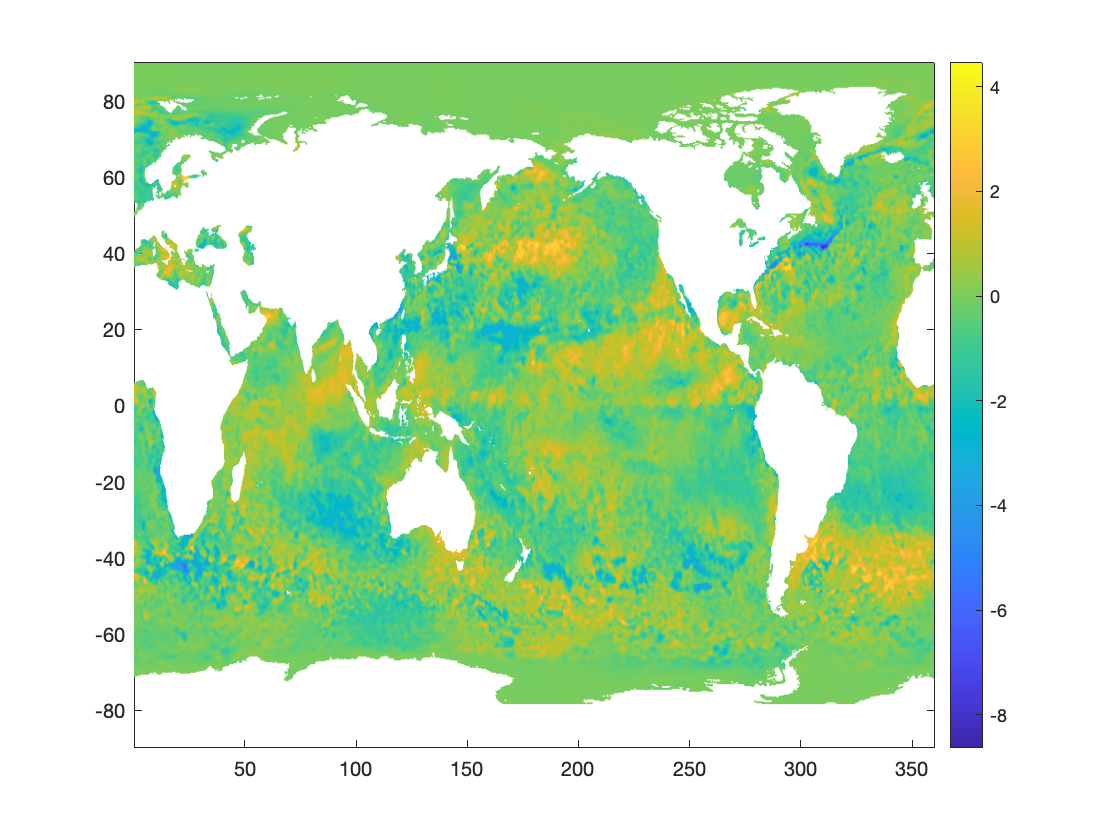

%% Calculate anomalies
sst_anom = sst1-clima(:,:,103); 

%% plot to check
lon1=repmat(lon,[1 length(lat)]);
lat1=repmat(lat,[1 length(lon)])';
figure;pcolor(lon1,lat1,sst_anom); shading flat;colorbar;

%% find coords

lon_start=187.6250; % closest to 187.5 in OISST grid
lat_start=62.6250; % closest to 62.5
idx_lon=find(lon==lon_start); % positioning
idx_lat=find(lat==lat_start);
idx1=find(lon>=lon(idx_lon)-1.25 & lon<=lon(idx_lon)+1.25) % coords range

idx1 =    746
   747
   748
   749
   750
   751
   752
   753
   754
   755


idx2=find(lat>=lat(idx_lat)-1.25 & lat<=lat(idx_lat)+1.25) % makes vector of 11 centered on lon/lat of interest

idx2 =    606
   607
   608
   609
   610
   611
   612
   613
   614
   615


%% confirm coords
lon(idx1)

ans = 11×1 single column vector
  186.3750
  186.6250
  186.8750
  187.1250
  187.3750
  187.6250
  187.8750
  188.1250
  188.3750
  188.6250


lat(idx2)

ans = 11×1 single column vector
   61.3750
   61.6250
   61.8750
   62.1250
   62.3750
   62.6250
   62.8750
   63.1250
   63.3750
   63.6250


%% SSTas on pixels around 187.6250,62.6250
sst2 = sst_anom(idx1,idx2)

sst2 = 11×11 single matrix
    1.3076    1.0870    0.7991    0.3241   -0.0685   -0.2922   -0.3145   -0.3240   -0.3042   -0.3152   -0.3094
    1.2319    0.9216    0.6358    0.1719   -0.2131   -0.3457   -0.3432   -0.3586   -0.3518   -0.3400   -0.3389
    1.0631    0.7561    0.3724   -0.0203   -0.3344   -0.3906   -0.3835   -0.3924   -0.4167   -0.3924   -0.3824
    0.8818    0.5952    0.1277   -0.2156   -0.4560   -0.4443   -0.4208   -0.4327   -0.4730   -0.4448   -0.3922
    0.6715    0.3938   -0.0289   -0.2799   -0.4696   -0.4450   -0.4225   -0.4785   -0.5142   -0.4750   -0.3894
    0.4027    0.1002   -0.0976   -0.2944   -0.4770   -0.4543   -0.4379   -0.4859   -0.5251   -0.4772   -0.3811
    0.3181   -0.0682   -0.1909   -0.3258   -0.4765   -0.4708   -0.4352   -0.4524   -0.4639   -0.4314   -0.3501
    0.1739   -0.0989   -0.1891   -0.3009   -0.4396   -0.4466   -0.3782   -0.3404   -0.3146   -0.3382   -0.3030
    0.1409   -0.0894   -0.1618   -0.2682   -0.3998   -0.4014   -0.3094   -0.2117   -0

pix_anom=squeeze(nanmean(nanmean(sst2)))

pix_anom = single
-0.1471